# Calculations by Group

This Live Script provides examples of calculating summary statistics by group and visualizing grouped data using the *patients* data set. This dataset is included with MATLAB and contains 100 observations from a blood pressure study.

## Initial Setup

Run the code below to load the patients dataset into a `table` and convert the text variables to `categorical` variables. Note that there is no missing data in this dataset.

### Load the dataset and convert to a `table`

In addition to the systolic and diastolic blood pressure measurements, the following variables are included for each participant:

- age

- gender

- height

- weight

- smoker status

- self-assessed health status

load patients
data = table(Age,Gender,Height,Weight,Smoker,SelfAssessedHealthStatus,Systolic,Diastolic);
clearvars -except data

### Convert text variables to `categorical` variables

Note that `Gender` is a nominal categorical variable with no implicit order (the MATLAB default), while `SelfAssessedHealthStatus` is an [ordinal](https://www.mathworks.com/help/matlab/matlab_prog/ordinal-categorical-arrays.html) categorical variable ordered from "Poor" to "Excellent".

data.Gender = categorical(data.Gender);
data.SelfAssessedHealthStatus = categorical(data.SelfAssessedHealthStatus,{'Poor','Fair','Good','Excellent'},'Ordinal',true);

### Inspect the dataset

Before performing calculations by group, it's important to understand each variable as a whole so that you can more easily identify, and better understand, any differences between groups. Run the code in this section, then use the interactive `table` output and the summary statistics to inspect the variables. Pay particular attention to the datatype of each variable, as well as the range and distribution of their values.

data

data = 100×8 table
    Age    Gender    Height    Weight    Smoker    SelfAssessedHealthStatus    Systolic    Diastolic
    ___    ______    ______    ______    ______    ________________________    ________    _________

    38     Male        71       176      true             Excellent              124          93    
    43     Male        69       163      false            Fair                   109          77    
    38     Female      64       131      false            Good                   125          83    
    40     Female      67       133      false            Fair                   117          75    
    49     Female      64       119      false            Good                   122          80    
 

### Summarize the dataset

summary(data)

Variables:

    Age: 100×1 double

        Values:

            Min          25   
            Median       39   
            Max          50   

    Gender: 100×1 categorical

        Values:

            Female       53   
            Male         47   

    Height: 100×1 double

        Values:

            Min          60   
            Median       67   
            Max          72   

    Weight: 100×1 double

        Values:

            Min          111  
            Median     142.5  
            Max          202  

    Smoker: 100×1 logical

        Values:

            True        34   
            False       66   

    SelfAssessedHealthStatus: 100×1 ordinal categorical

        Values:

            Poor            11   
            Fair            15   
            Good            40   
            Excellent       34   

    Systolic: 100×1 double

      

## Calculating statistics by group

The examples below use the `groupsummary` function to calculate summary statistics on one or more variables by group. See the [documentation](https://www.mathworks.com/help/matlab/ref/double.groupsummary.html) for more information and additional options.

### Calculate the median weight by gender

While inspecting the variables, you may have noticed a split in the distribution of weight values as shown below. 

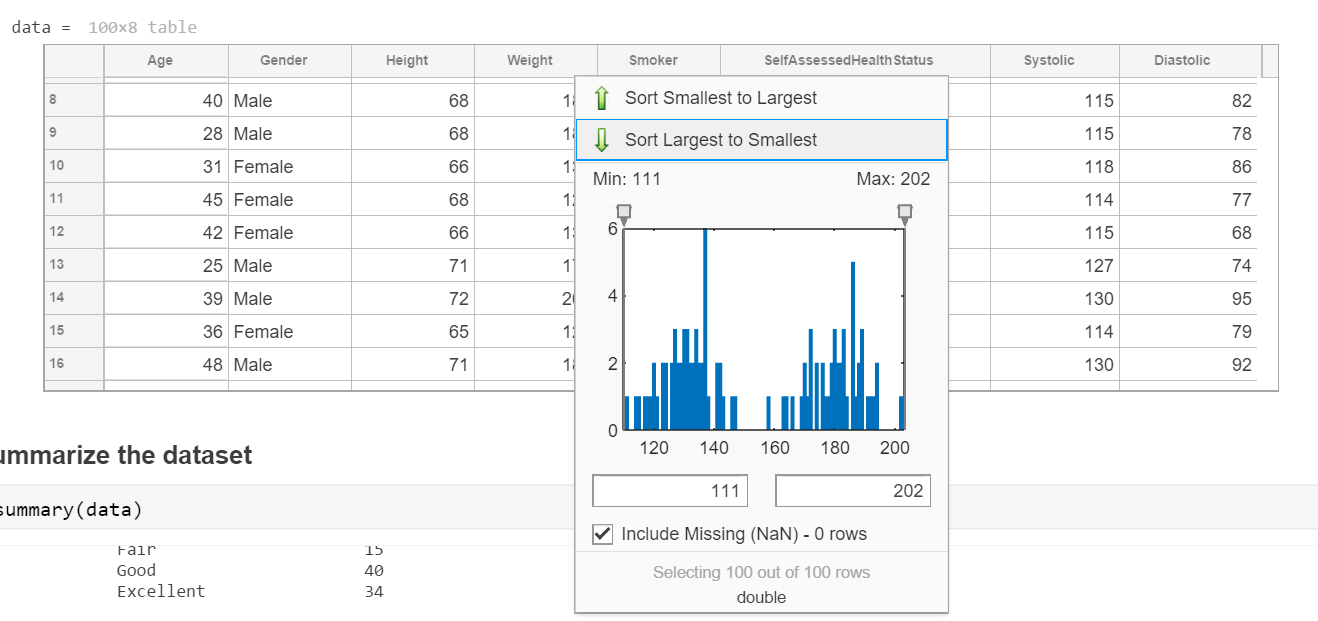

A natural assumption is that this is due to a difference in one of the other variables, the most likely being patient gender. To investigate this further, run the code below to calculate the median of `Weight` grouped by `Gender`.

groupsummary(data,'Gender','median','Weight')

ans = 2×3 table
    Gender    GroupCount    median_Weight
    ______    __________    _____________

    Female        53             131     
    Male          47             181     


### Calculate the mean, min, and maximum weight by gender

As you might expect, the results show a clear difference between males and females when it comes to median body weight. Note also that there are actually very few participant weights near the *overall* median value of 142.5 computed earlier. To confirm that gender is the most likely reason for the observed split in the distribution of weight variables, compute and inspect the mean, minimum and maximum values for each gender by running the code below. Note that multiple statistics can be calculated at once by grouping them using curly braces.

groupsummary(data,'Gender',{'min','mean','max'},'Weight')

ans = 2×5 table
    Gender    GroupCount    min_Weight    mean_Weight    max_Weight
    ______    __________    __________    ___________    __________

    Female        53           111          130.47          147    
    Male          47           158          180.53          202    


The results above confirm that the two groups seen in the `Weight` variable are due primarily to gender differences.

### Calculate the mean of `Systolic` and `Diastolic` by `Smoker`

Not all potential group relationships are as easy to spot as the previous one. For example, smoking is a leading cause of [hypertension](https://en.wikipedia.org/wiki/Hypertension), or high blood pressure. Run the code below to calculate the mean of both blood pressure variables by smoking status (1 = smoker, 0 = nonsmoker). Do the results agree with this assertion?

groupsummary(data,'Smoker','mean',{'Systolic','Diastolic'})

ans = 2×4 table
    Smoker    GroupCount    mean_Systolic    mean_Diastolic
    ______    __________    _____________    ______________

    false         66           119.39            79.379    
    true          34           129.35            89.912    


### Calculate the mean of `Systolic` and `Diastolic` by `SelfAssessedHealthStatus`

Are people able to accurately gauge their own health, at least when it comes to blood pressure? Run the code below to calculate the mean of the blood pressure measurements by self-assessed health status. Are the results what you expected?

groupsummary(data,'SelfAssessedHealthStatus','mean',{'Systolic','Diastolic'})

ans = 4×4 table
    SelfAssessedHealthStatus    GroupCount    mean_Systolic    mean_Diastolic
    ________________________    __________    _____________    ______________

           Poor                     11           122.45            81.818    
           Fair                     15           120.33            82.867    
           Good                     40              124             83.25    
           Excellent                34           122.53            83.029    


### Calculate the mean of `Systolic` and `Diastolic` by `SelfAssessedHealthStatus` using only two groups

It turns out those who rated their health "Good" and "Excellent" have *higher* blood pressures than those who rated their health as "Fair" or "Poor". Since the latter groups are relatively small, the code below combines them into a single group (0), with those who rated their health higher combined into a separate group (1) using the '>' relational operator. Such grouping operations are common with ordinal categorical variables.

grp = data.SelfAssessedHealthStatus > 'Fair';

Note that since the new two-tier health status variable isn't part of the same table, the vector/matrix syntax for calling `groupsummary` is used instead of the `table` syntax. See the documentation for more details.

groupsummary([data.Systolic,data.Diastolic],grp,'mean')

ans =   121.2308   82.4231
  123.3243   83.1486


The rows are ordered by increasing group number, so the first row corresponds to the blood pressure means for group 0 ("Fair" or "Poor") and the second for group 1 ("Good" or "Excellent"). Note that the difference in mean blood pressure remains even with the combined groups.

## Visualizing group relationships

Visualizations can also help identify different behaviors within grouped data. The examples below use common visualization techniques for grouped data.

### Generate a heat map of self-assessed health and smoker status

In the previous section, it was shown that, somewhat counterintuitively, those who rated their own health as "Good" or better had higher blood pressure on average than those who rated their health lower. Since it was already shown that smokers have a significantly higher blood pressure than nonsmokers, it is natural to ask how smokers rate their own health, and in particular, if a high number of smokers rating their own health favorably might be the reason for the increased blood pressure in those groups. Run the code below to explore this question.

- One way to help answer this question is to use `groupsummary` to obtain the proportion of smokers making up each health status group: 

groupsummary(data,'SelfAssessedHealthStatus','mean','Smoker')

ans = 4×3 table
    SelfAssessedHealthStatus    GroupCount    mean_Smoker
    ________________________    __________    ___________

           Poor                     11          0.27273  
           Fair                     15          0.33333  
           Good                     40              0.4  
           Excellent                34          0.29412  


- Alternatively, a table of the raw counts for smokers vs nonsmokers broken down by health status can be obtained using the [`crosstab`](https://www.mathworks.com/help/stats/crosstab.html) function as below. Note that the rows and columns are ordered by increasing category number which are Poor $\to$ Excellent for health status and Nonsmoker $\to$ Smoker for smoker status.

crosstab(data.SelfAssessedHealthStatus,data.Smoker)

ans =      8     3
    10     5
    24    16
    24    10


Lastly, the same information from the cross-tabulation can be generated and conveyed *visually* using the [`heatmap`](https://www.mathworks.com/help/matlab/ref/heatmap.html) function. Before generating the heat map, the 'Smoker' variable is converted to a `categorical` for improved labeling in the visual.

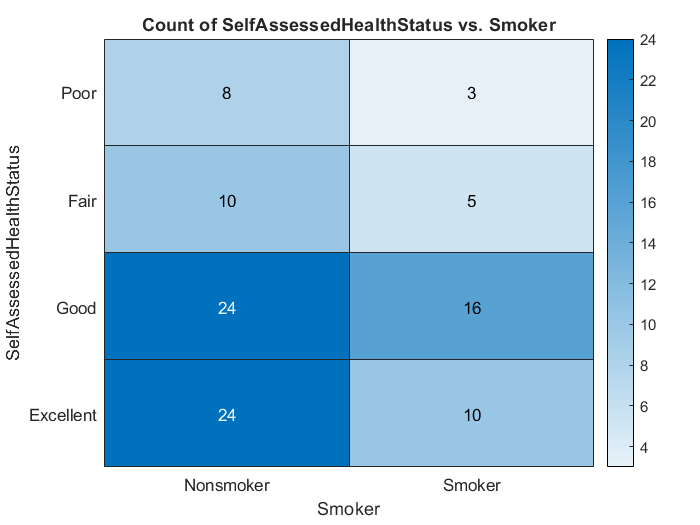

% First, convert Smoker to a categorical variable for use with gplotmatrix
data.Smoker = categorical(data.Smoker,[false,true],{'Nonsmoker','Smoker'});
heatmap(data,'Smoker','SelfAssessedHealthStatus');

Heatmaps are especially helpful in identifying over and under-represented groups in your data which can skew analysis and produce misleading results. From the outputs above, it is clear that the health status group with the highest percentage of smokers is "Good", which, unsurprisingly, is the group with the highest mean blood pressure.

### Generate a scatter plot using grouped data

Scatter plots can be very helpful when exploring potential relationships between variables. However, some relationships may only hold for certain groups, or the relationship type or parameters may change by group. These subtleties are difficult to determine from the scatter plot alone, and in these cases it's helpful to [add group information to the scatter plot](https://www.mathworks.com/help/stats/scatter-plots.html). Run the code below to plot `Diastolic` vs `Weight` grouped by `Gender` using the [`gscatter`](https://www.mathworks.com/help/stats/gscatter.html) function.

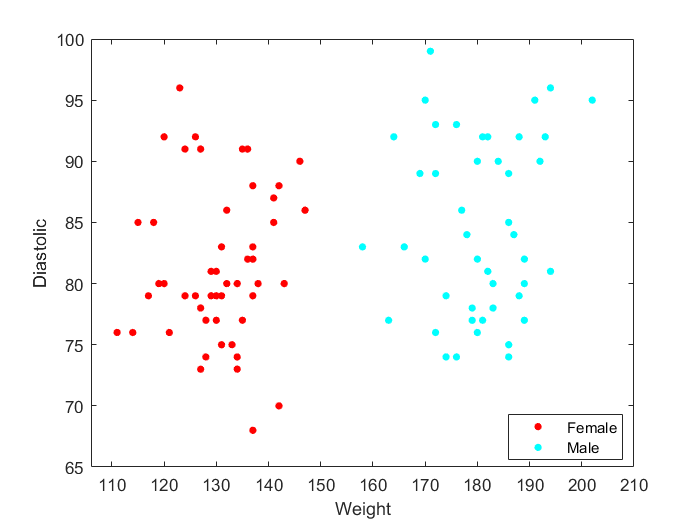

gscatter(data.Weight,data.Diastolic,data.Gender);
xlabel('Weight');
ylabel('Diastolic')

### Generate a scatter plot matrix using a grouping variable

If you are exploring data with a large number of variables, a grouped scatter plot for multiple variable combinations can be generated simultaneously using the [`gplotmatrix`](https://www.mathworks.com/help/stats/gplotmatrix.html) function. Use the control below to select a grouping variable and generate a grouped scatter plot matrix. The additional input arguments are provided to `gplotmatrix` to add variable names to the plot for increased clarity. See the documentation for more details and function options.

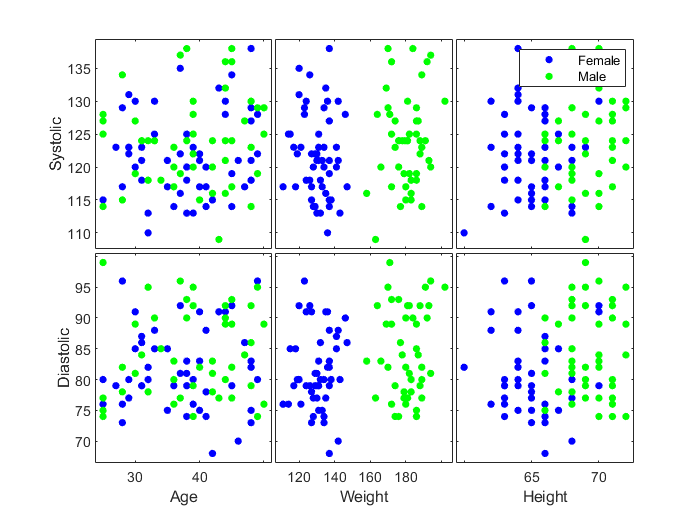

grp = data.Gender;
gplotmatrix([data.Age,data.Weight,data.Height],[data.Systolic,data.Diastolic],grp,...
    [],[],[],[],[],{'Age','Weight','Height'},{'Systolic','Diastolic'})

## Further practice with group statistics and visualization

Use what you learned above to continue calculating statistics by group and visualizing grouped data using the patients dataset. 

- For example, try creating a new variable by calculating the BMI of each patient and inspecting the values of BMI by group. 

- You can also import one of the other [datasets included with MATLAB](https://www.mathworks.com/help/stats/sample-data-sets.html), or use the Import Tool to import your own dataset and explore the data by calculating group statistics and visualizing grouped variables. 

% Your code here:

